xt0 = -1.8000e-05

x = 	1.0e+-4 *

   -0.1800   -0.1800   -0.1799   -0.1799   -0.1799   -0.1798   -0.1798   -0.1797   -0.1797   -0.1797   -0.1796   -0.1796   -0.1796   -0.1795   -0.1795   -0.1795   -0.1794   -0.1794   -0.1794   -0.1793   -0.1793   -0.1792   -0.1792   -0.1792   -0.1791   -0.1791   -0.1791   -0.1790   -0.1790   -0.1790   -0.1789   -0.1789   -0.1788   -0.1788   -0.1788   -0.1787   -0.1787   -0.1787   -0.1786   -0.1786   -0.1786   -0.1785   -0.1785   -0.1785   -0.1784   -0.1784   -0.1783   -0.1783   -0.1783   -0.1782


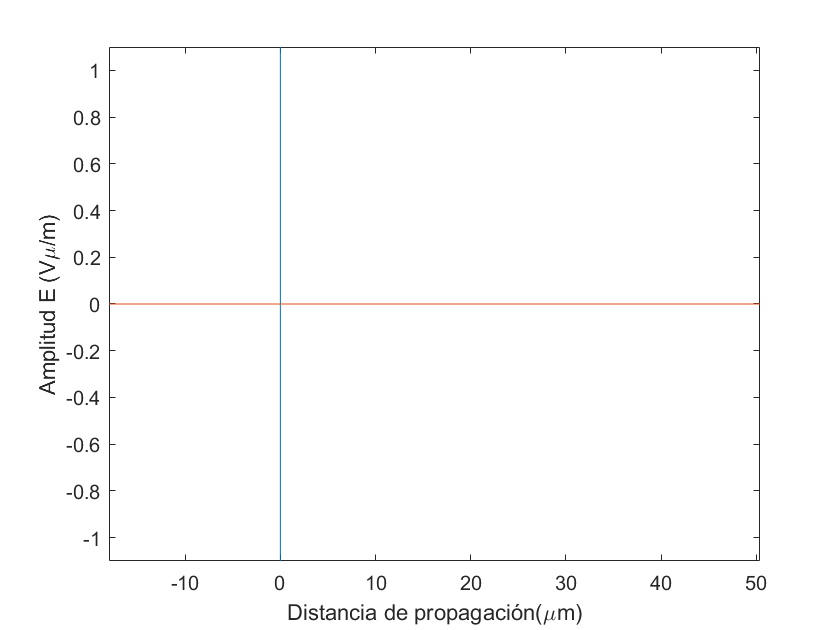

j = 1

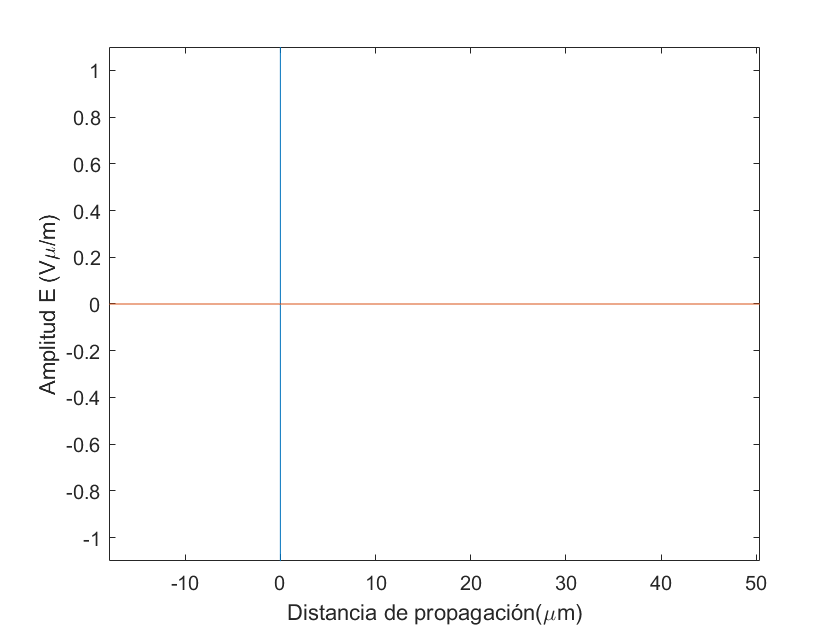

j = 2

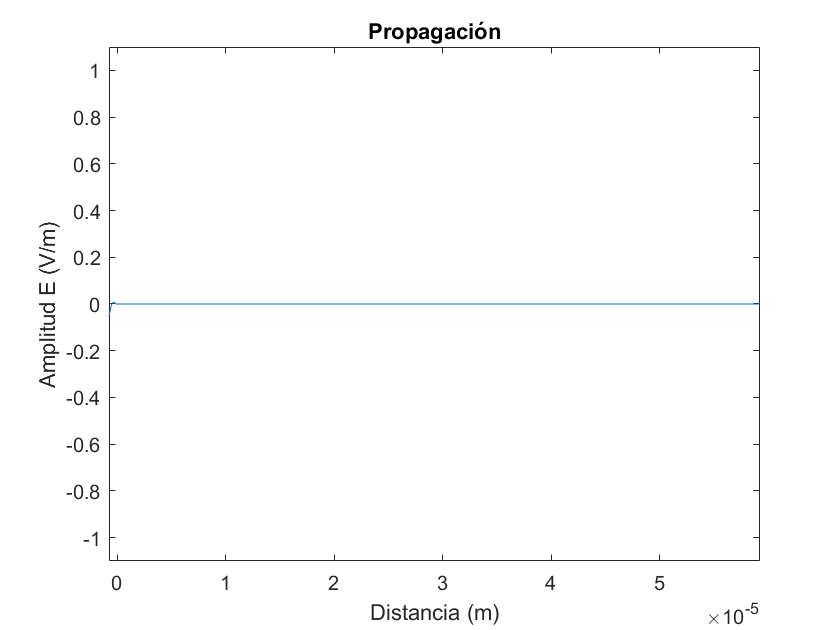

j = 3

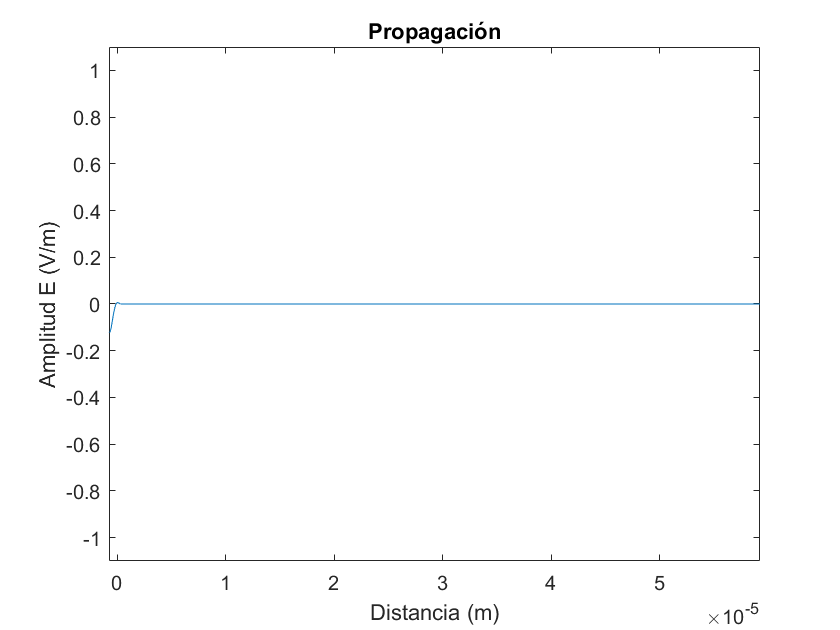

j = 4

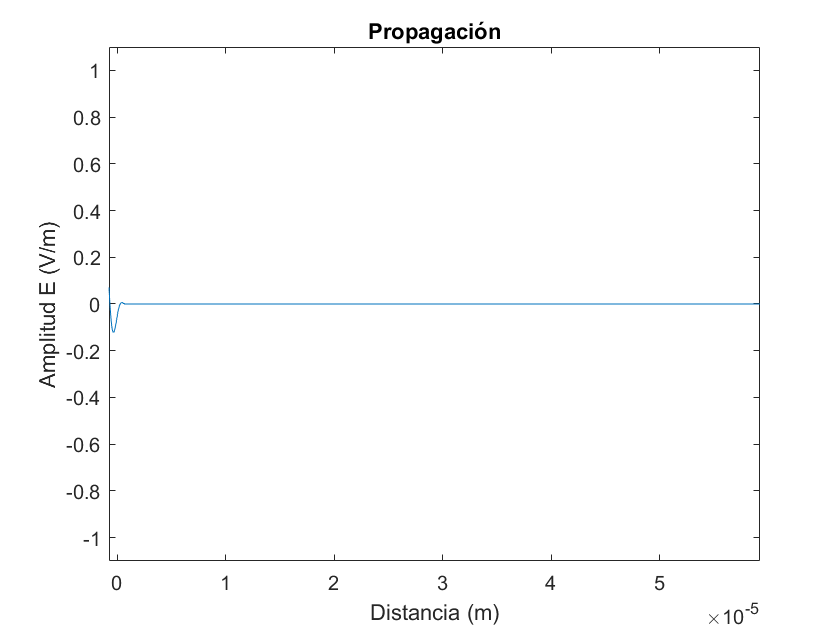

j = 5

j = 6

j = 7

j = 8

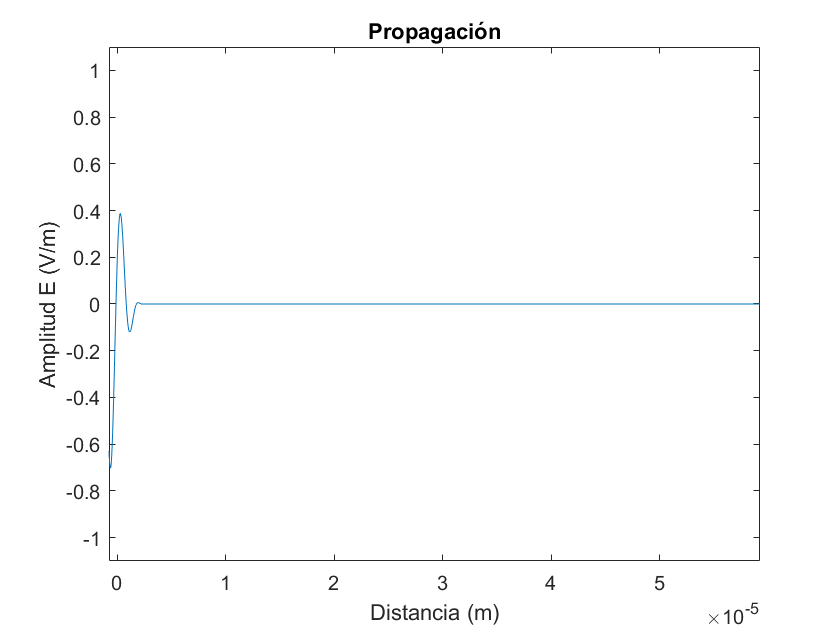

j = 9

j = 10

j = 11

j = 12

j = 13

j = 14

j = 15

j = 16

j = 17

j = 18

j = 19

j = 20

j = 21

j = 22

j = 23

j = 24

j = 25

j = 26

j = 27

j = 28

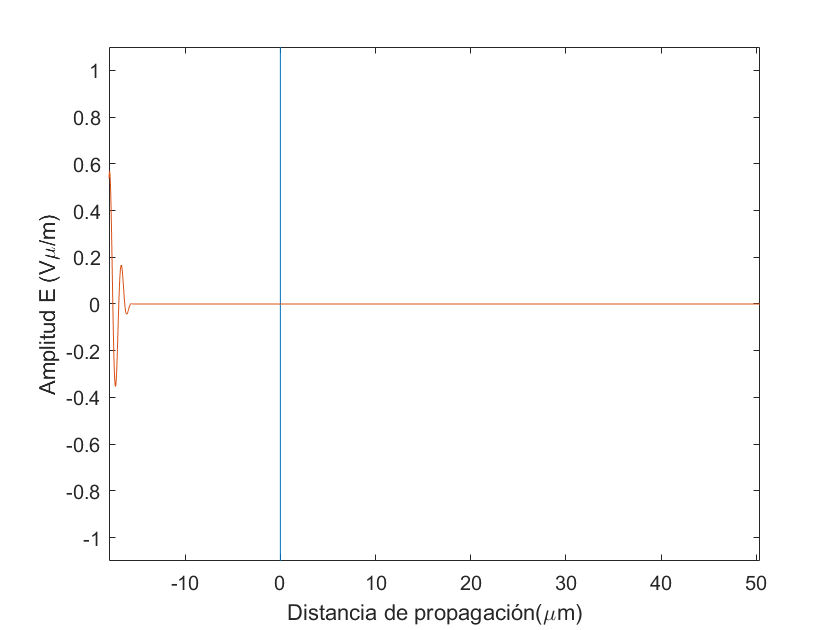

j = 29

j = 30

j = 31

j = 32

j = 33

j = 34

j = 35

j = 36

j = 37

j = 38

j = 39

j = 40

j = 41

j = 42

j = 43

j = 44

j = 45

j = 46

j = 47

j = 48

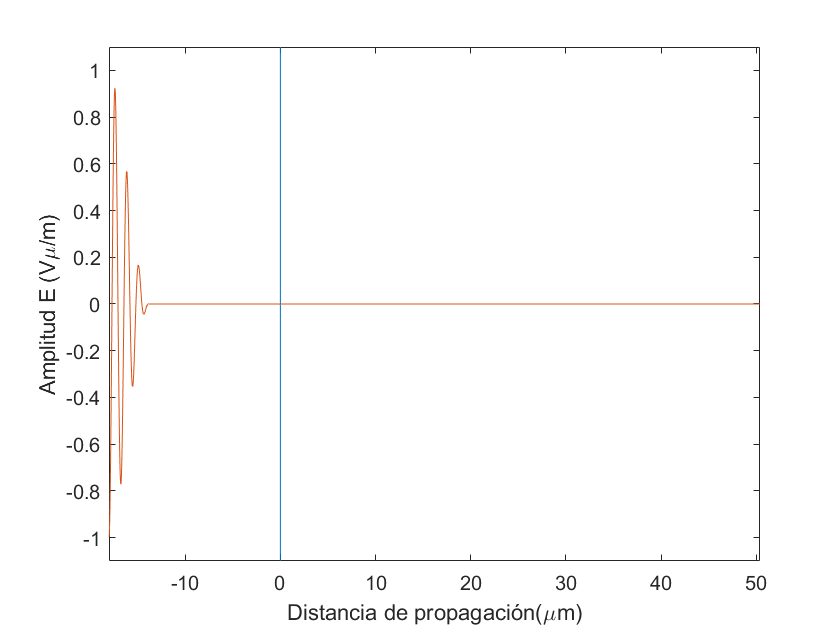

j = 49

j = 50

j = 51

j = 52

j = 53

j = 54

j = 55

j = 56

j = 57

j = 58

j = 59

j = 60

j = 61

j = 62

j = 63

j = 64

j = 65

j = 66

j = 67

j = 68

j = 69

j = 70

j = 71

j = 72

j = 73

j = 74

j = 75

j = 76

j = 77

j = 78

j = 79

j = 80

j = 81

j = 82

j = 83

j = 84

j = 85

j = 86

j = 87

j = 88

j = 89

j = 90

j = 91

j = 92

j = 93

j = 94

j = 95

j = 96

j = 97

j = 98

j = 99

j = 100

j = 101

j = 102

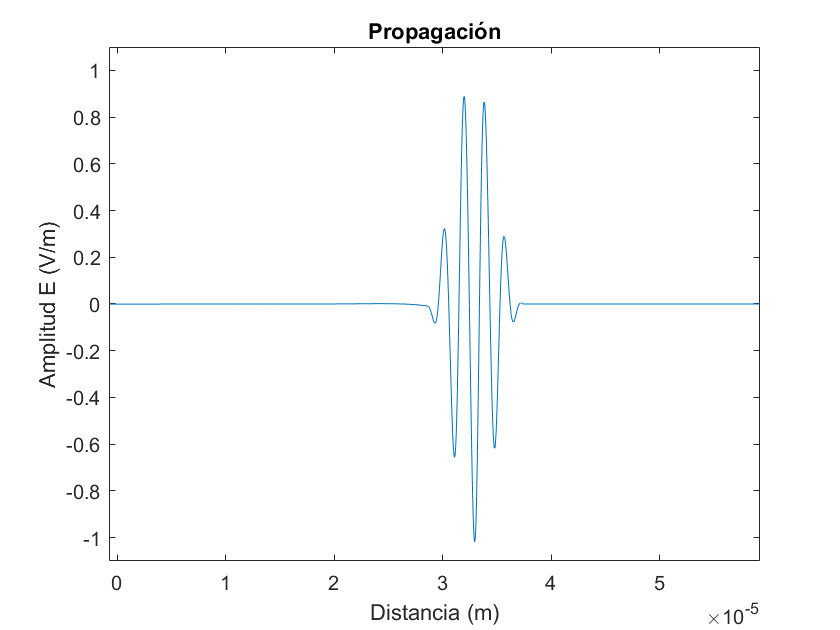

j = 103

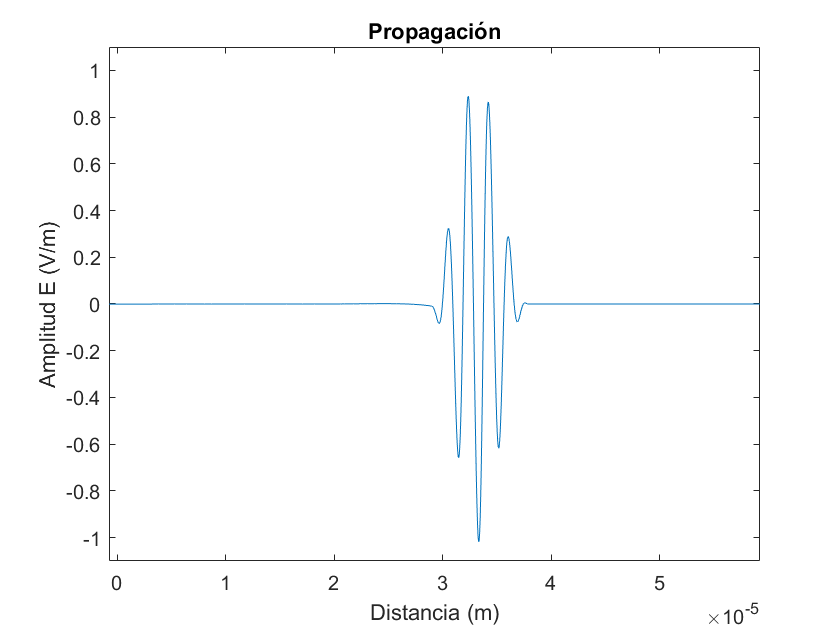

j = 104

j = 105

j = 106

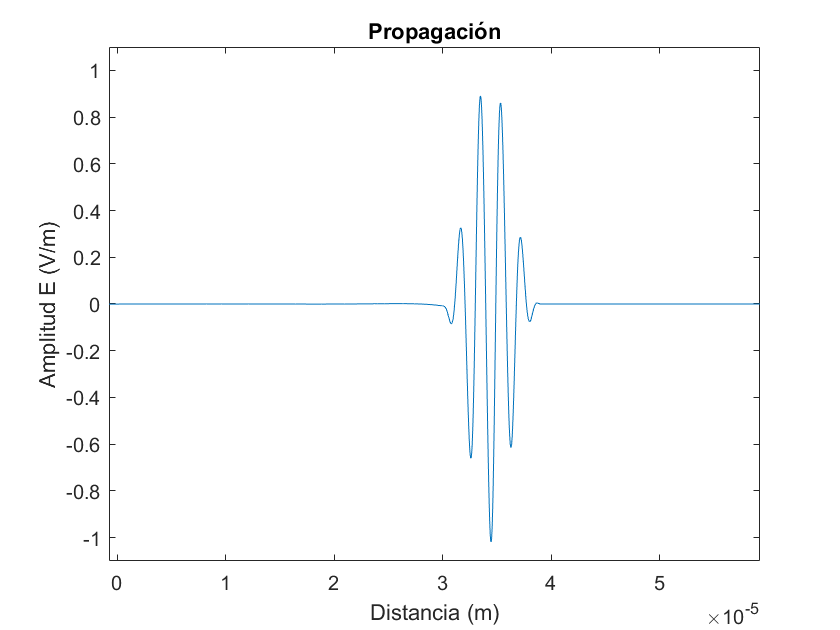

j = 107

j = 108

j = 109

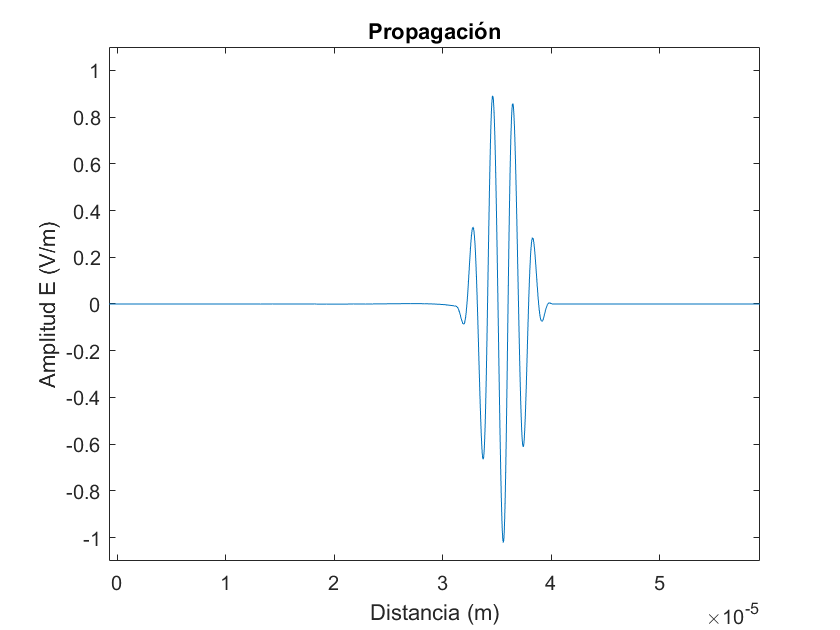

j = 110

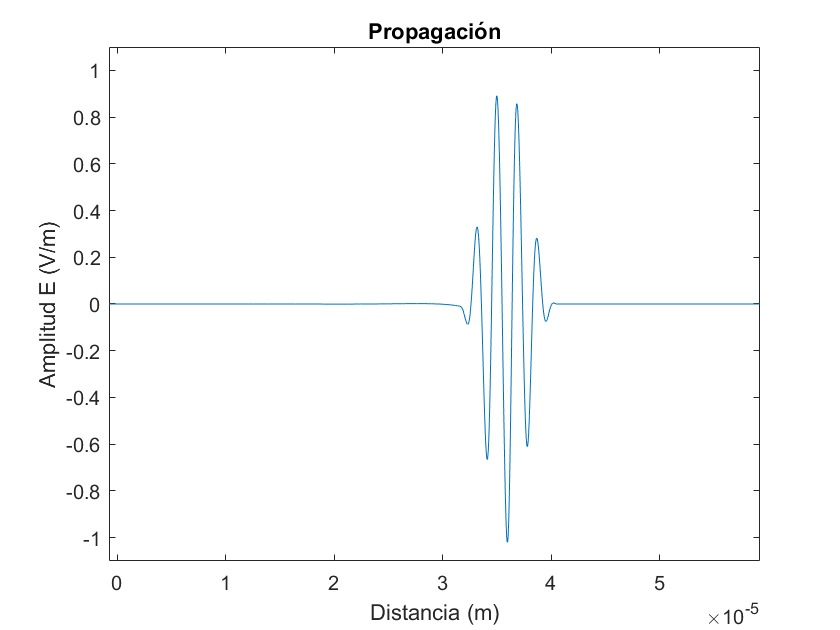

j = 111

j = 112

j = 113

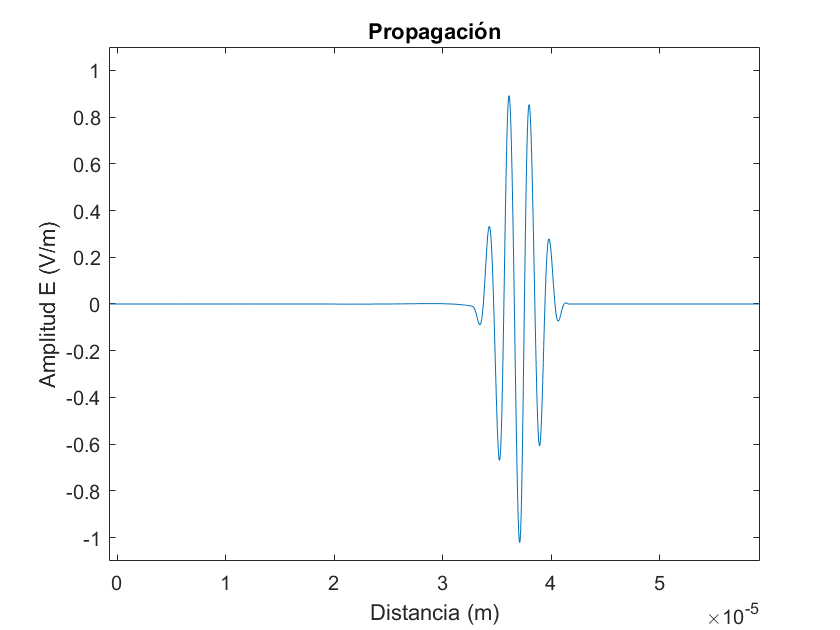

j = 114

j = 115

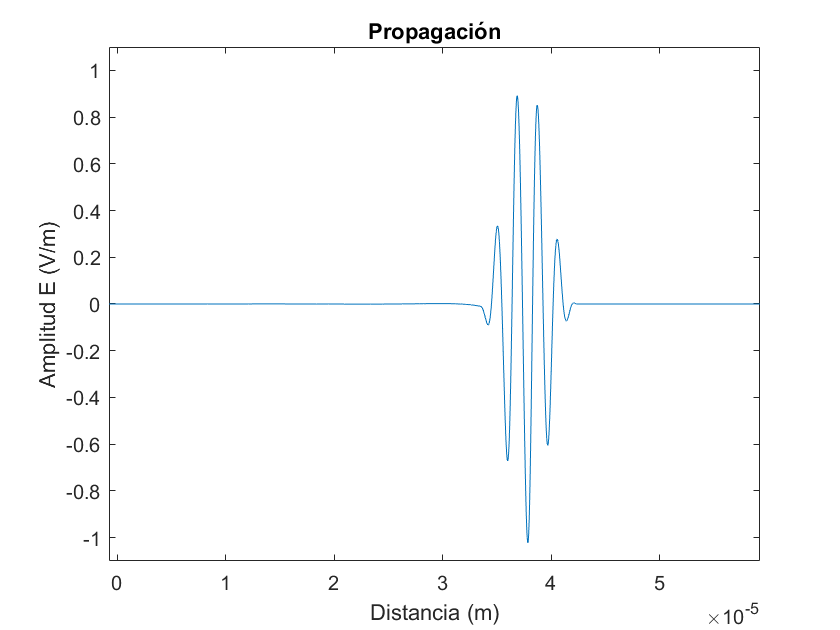

j = 116

j = 117

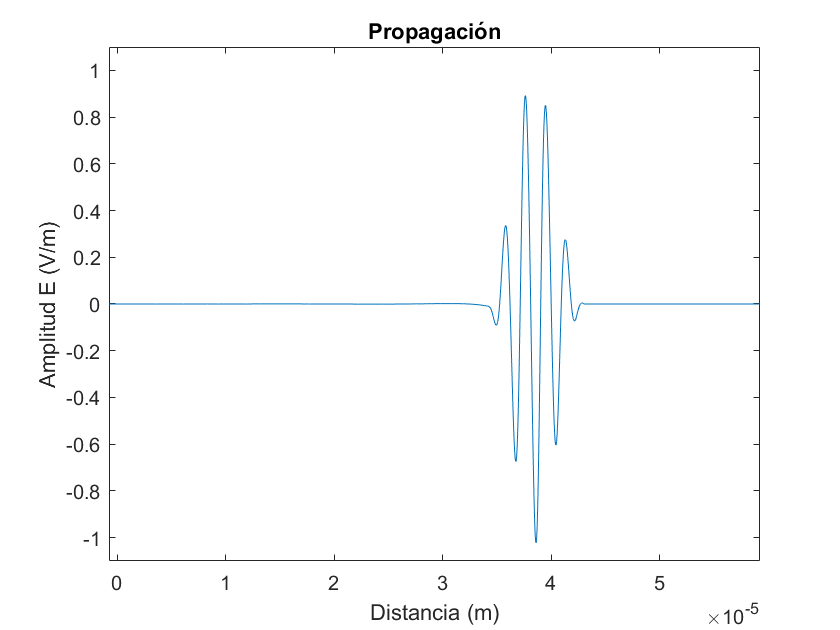

j = 118

j = 119

j = 120

j = 121

j = 122

j = 123

j = 124

j = 125

j = 126

j = 127

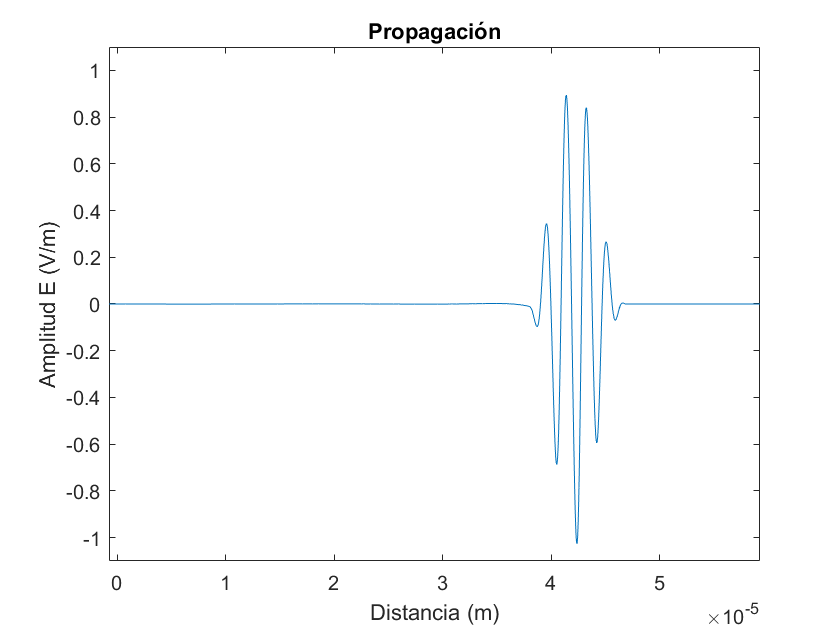

j = 128

j = 129

j = 130

j = 131

j = 132

j = 133

j = 134

j = 135

j = 136

j = 137

j = 138

j = 139

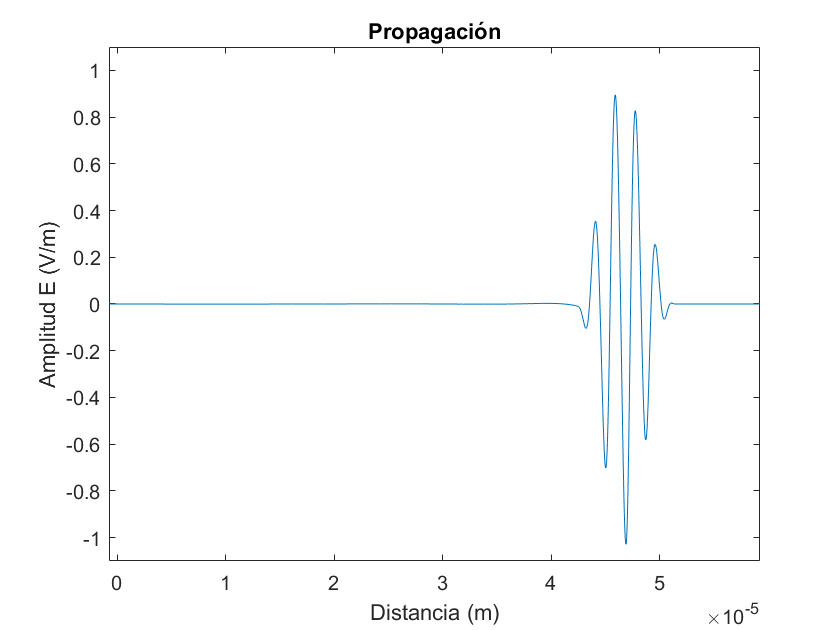

j = 140

j = 141

j = 142

j = 143

j = 144

j = 145

j = 146

j = 147

j = 148

j = 149

j = 150

j = 151

j = 152

j = 153

j = 154

j = 155

j = 156

j = 157

j = 158

j = 159

j = 160

j = 161

j = 162

j = 163

j = 164

j = 165

j = 166

j = 167

j = 168

j = 169

j = 170

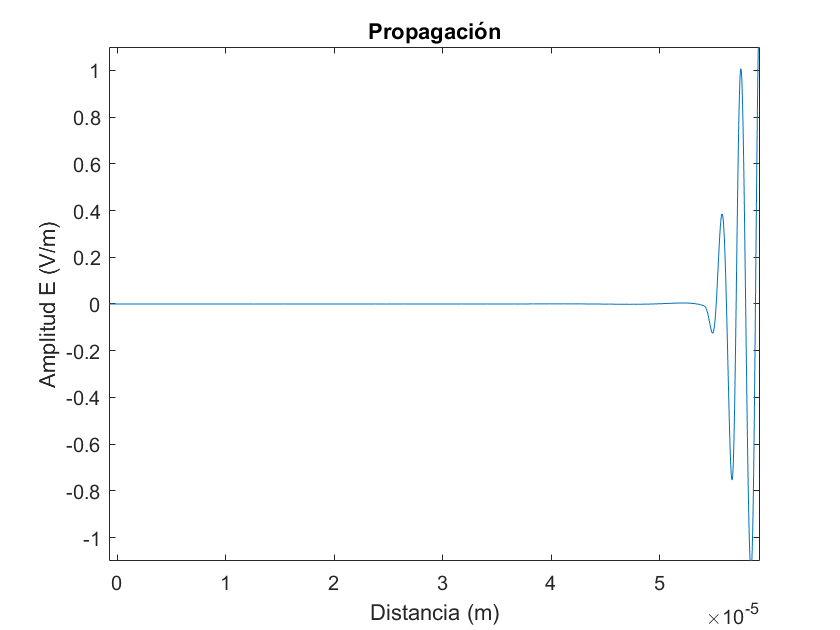

j = 171

j = 172

j = 173

j = 174

j = 175

j = 176

j = 177

j = 178

j = 179

j = 180

j = 181

j = 182

j = 183

j = 184

j = 185

j = 186

j = 187

j = 188

j = 189

j = 190

j = 191

j = 192

j = 193

j = 194

j = 195

j = 196

j = 197

j = 198

j = 199

j = 200

j = 201

j = 202

j = 203

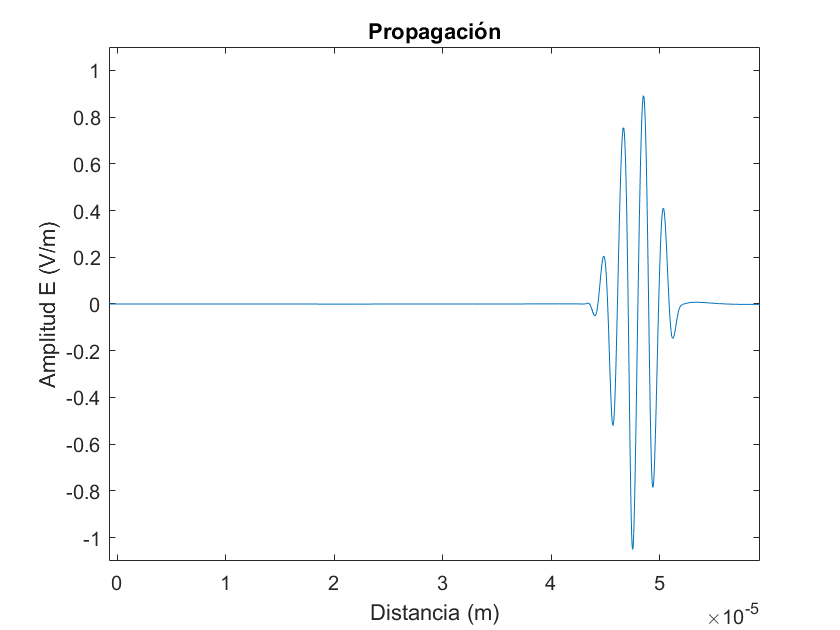

j = 204

j = 205

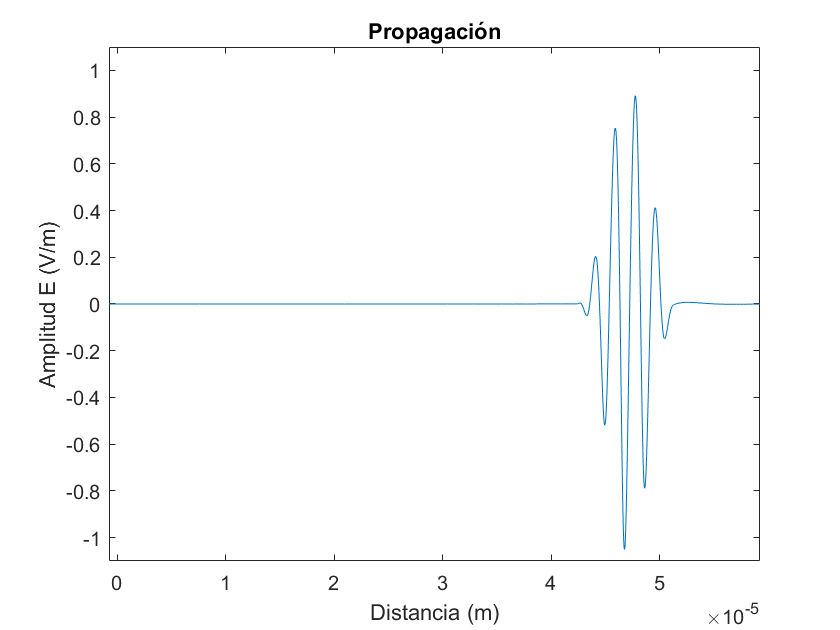

j = 206

j = 207

j = 208

j = 209

j = 210

j = 211

j = 212

j = 213

j = 214

j = 215

j = 216

j = 217

j = 218

j = 219

j = 220

j = 221

j = 222

j = 223

j = 224

j = 225

j = 226

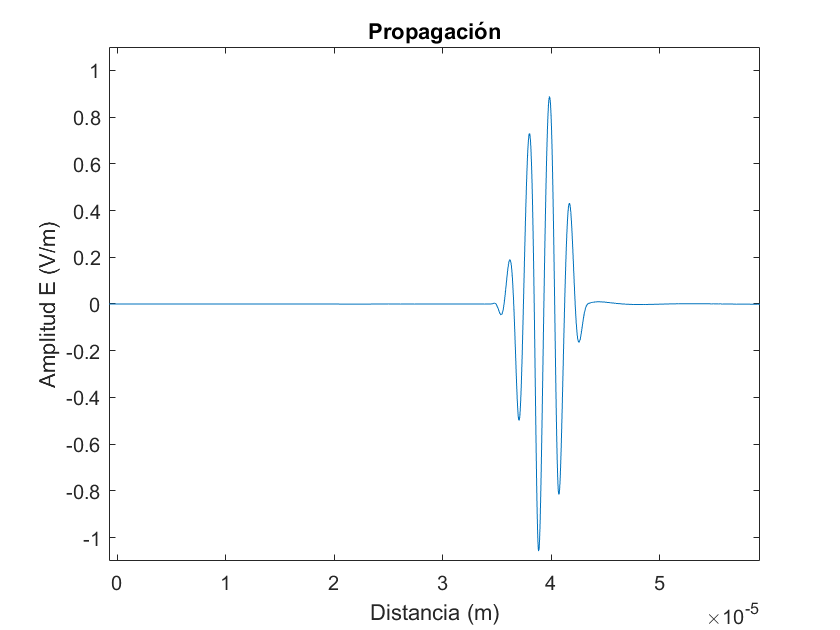

j = 227

j = 228

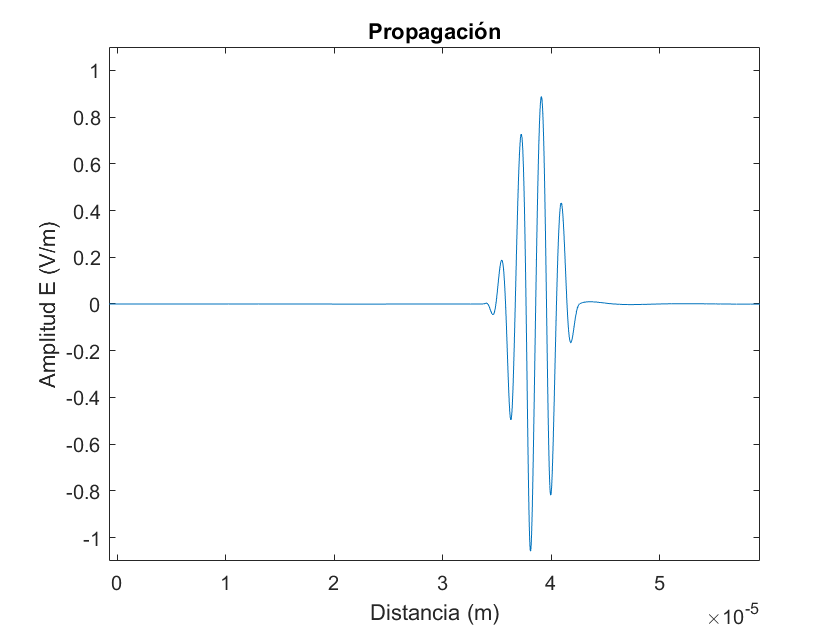

j = 229

j = 230

j = 231

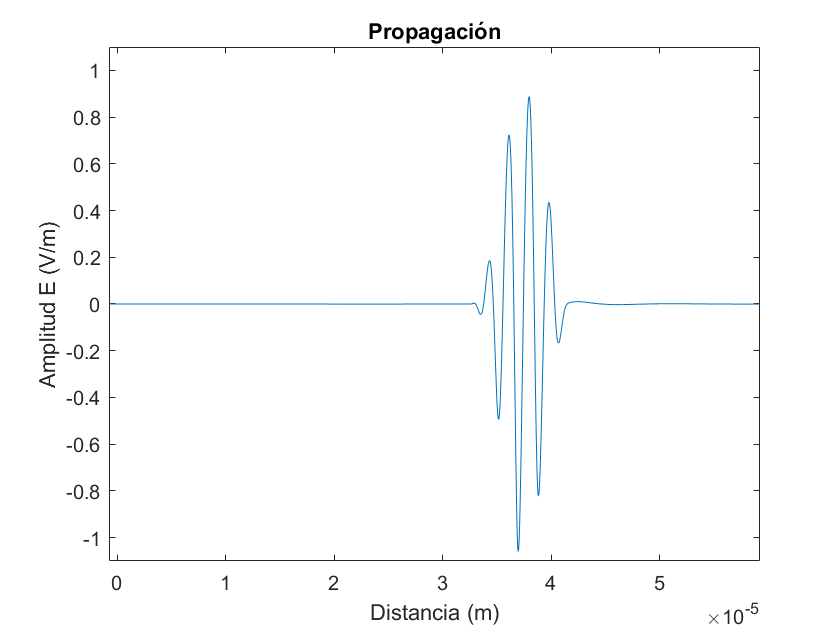

j = 232

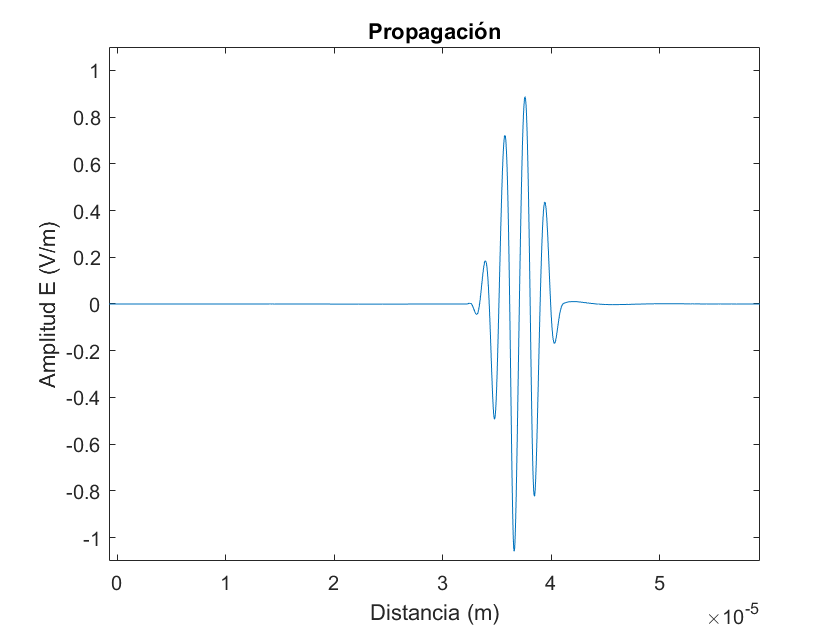

j = 233

j = 234

j = 235

j = 236

j = 237

j = 238

j = 239

j = 240

j = 241

j = 242

j = 243

j = 244

j = 245

j = 246

j = 247

j = 248

j = 249

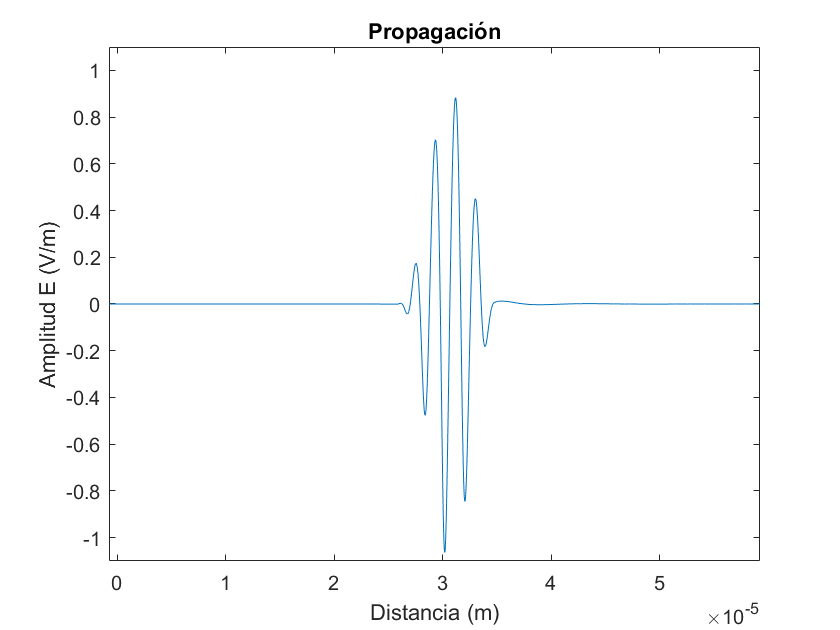

j = 250

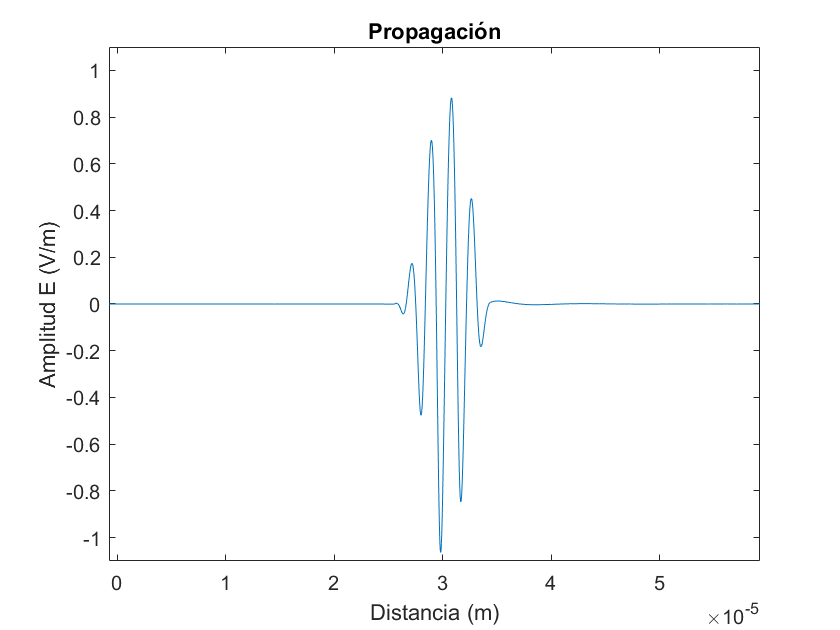

j = 251

j = 252

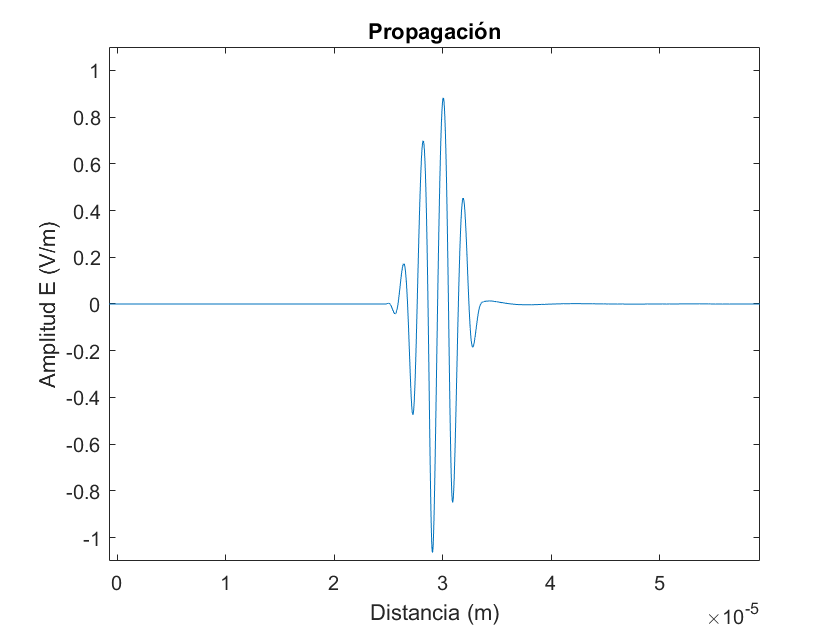

j = 253

j = 254

j = 255

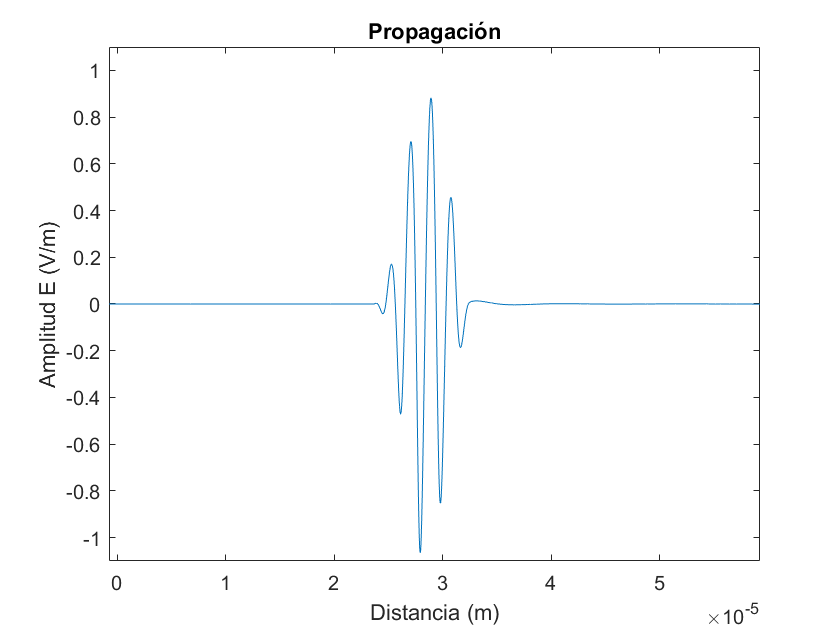

j = 256

j = 257

j = 258

j = 259

j = 260

j = 261

j = 262

j = 263

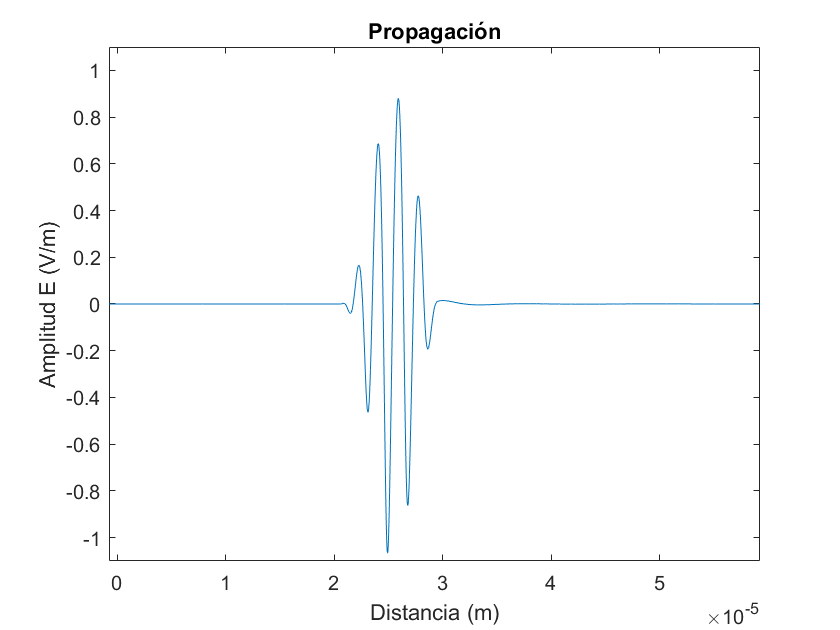

j = 264

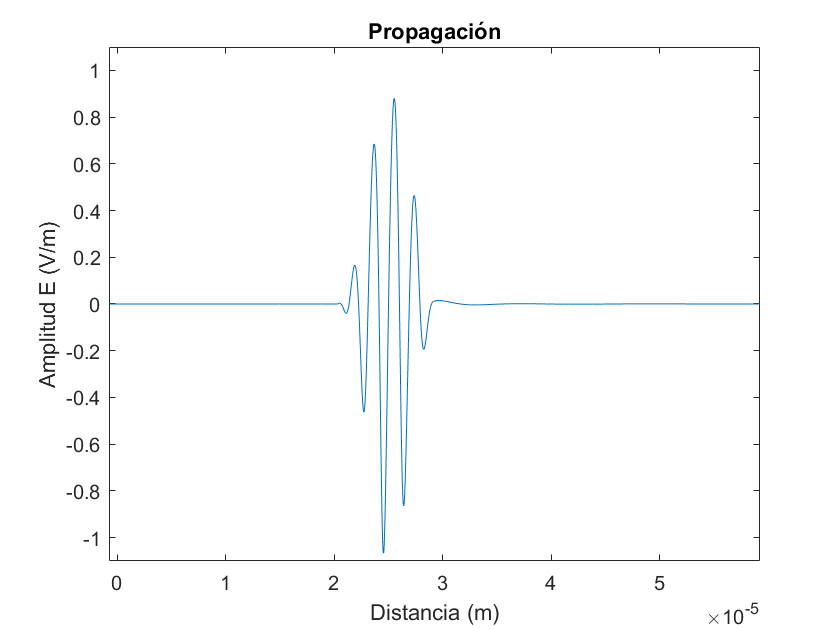

j = 265

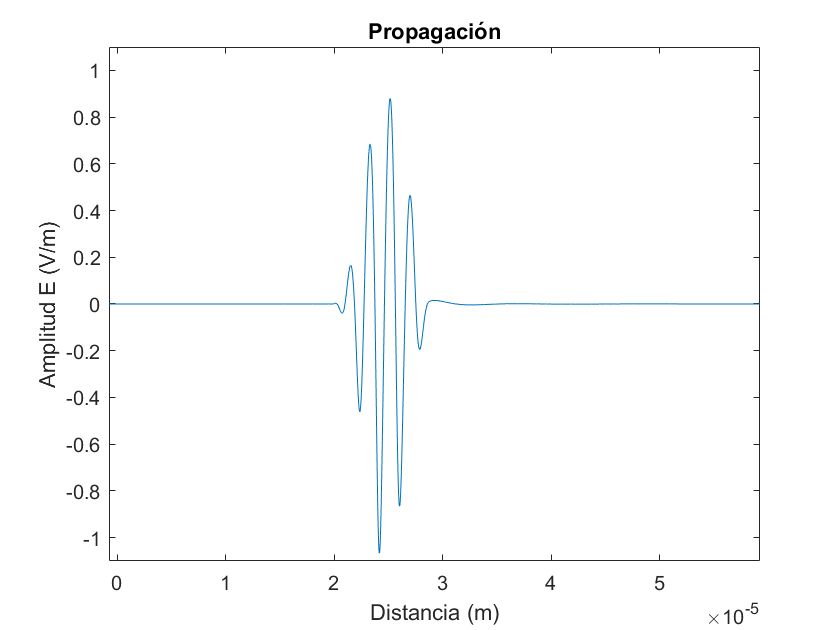

j = 266

j = 267

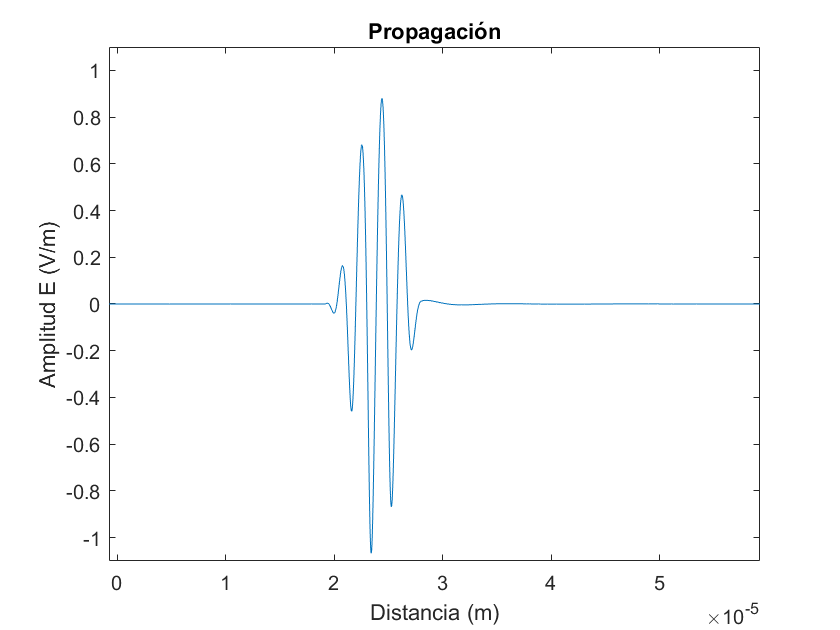

j = 268

j = 269

j = 270

j = 271

j = 272


rect = [0, 0, 520, 410]; % Size of the video frame

% Vector in the form: [left bottom width height]

%____________________________Propagation Video____________________________
nomFile = sprintf('Etvideo.txt');
Esp = importdata(nomFile, '');

bi = 1;
bf = Esp(1,1);
fotos = Esp(2,1);
deltaTime = Esp(3,1) * 10^-15;
wall = Esp(4,1);
c = 3 * 10^8;
deltaSpace = deltaTime * c;
xt0 = -deltaSpace * wall;
xtfin = xt0 + deltaSpace * (bf - 1);
x = (xt0:deltaSpace:xtfin); % Vector with mesh nodes

CampoE(fotos) = struct('cdata',[],'colormap',[]); % Array to store each capture

for j = 1:1:fotos % Frame loop
    aa = 5 + bf * (j - 1); % Position of node 1 in Etvideo.txt for a specific time
    bb = 4 + bf * j; % Position of the final node in Etvideo.txt for a specific time
    y = Esp(aa:bb, 1);
    figure % Representation of each frame is stored as a figure
    xlinea = [0 0];
    ylinea = [-2 2];
    plot(xlinea, ylinea)
    hold on
    plot(x * 10^6, y)
    xlim([xt0 * 10^6 xtfin * 10^6])
    ylim([-1.1 1.1]); % Fix the y-axis
    % Representation configuration
    title(' ', 'FontSize', 16, 'FontName', 'Helvetica');
    xlabel('Propagation Distance (\mum)', 'FontSize', 12, 'FontName', 'Helvetica');
    ylabel('Amplitude E (V/\mum)', 'FontSize', 12, 'FontName', 'Helvetica');
    set(gca, 'FontSize', 10, 'FontName', 'Helvetica');
    hold off
    CampoE(j) = getframe(gcf, rect);
    % gcf: Capture the interior of the figure window excluding the menu and toolbars
    % rect: Capture the specified pixels in rect
    j
end

% Create the video
v = VideoWriter('Propagation_Video.avi', 'Motion JPEG AVI');
% Video file in the specified format and name
v.FrameRate = 6;
v.Quality = 99;
open(v); % Open the video
writeVideo(v, CampoE);
% Write the CampoE data matrix to the video file v
close(v); % Close the video

